# Working with the cMosaic data.

Extracts an ROI from the optimized cone mosaic, I think

Extracts isomerizations from an irregular set of positions in the mosaic using inpolygon.

Wandell

**See also:**

ieInit;

## Make a special version of the rings and rays

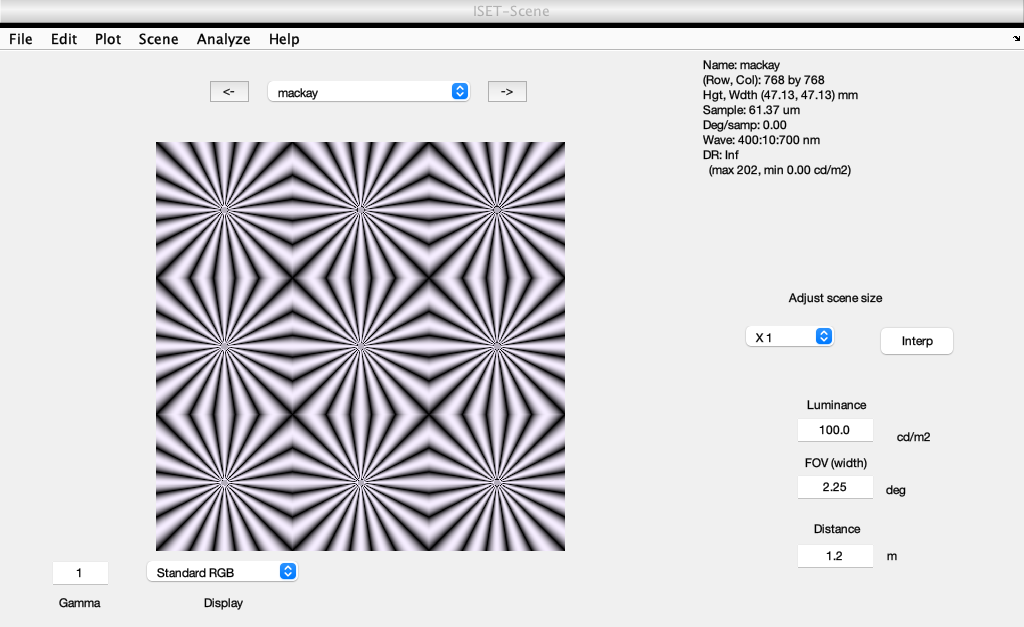

nRays    = 10;
nSamples = 256;
fov      = 0.75;
scene = sceneCreate('ringsrays', nRays, nSamples);
scene = sceneSet(scene, 'fov', fov);
scene = sceneCombine(scene, scene,'direction','centered');
sceneWindow(scene);

## Onward to oi and coneMosaic

oi = oiCreate('wvf human');
oi = oiCompute(scene, oi);

## Generate cMosaic centered at target eccentricity

hfov = sceneGet(scene,'hfov');
vfov = sceneGet(scene,'vfov');
fprintf('Creating cone mosaic %3.2f by %3.2f deg\n',hfov,vfov);

tic
cm = cMosaic(...
    'sizeDegs', [hfov vfov], ...   % (x,y)
    'eccentricityDegs', [0 0] ...  % Probably not necessary
    );
toc

## Compute the noise-free cone excitations

[noiseFreeExcitations, noisyExcitations] = cm.compute(oi);

## Extract the excitation data and visualize

Get the possible parameters

vParams = cm.visualize('params')

Set the parameters we want

vParams.activation = noisyExcitations;
vParams.activationColorMap = hot(256);
vParams.verticalActivationColorBar = true;
vParans.activationRange = [0 max(noisyExcitations)];
vParams.backgroundColor = [0.3 0.5 0.7];  % Not sure this works
vParams.visualizedConeAperture = 'lightCollectingArea';
vParams.domain = 'degrees';

Visualize

cm.visualize(vParams);

## Visualize a ROI

Here is some code that extracts responses from a desired ROI.

% To do:
%{
  cm.get('excitations',noiseFreeExcitations,roi);
%}

% Maybe an ROI class
%{
thisROI = roi(roiType);
switch roiType
case 'circle'
case 'line'
otherwise
end
%}


Define a circular ROI

roi = struct('center', [0 0], 'radius', 0.1);


Compute border of the ROI

roiBorderX = roi.center(1) + roi.radius*cosd(0:10:360);
roiBorderY = roi.center(2) + roi.radius*sind(0:10:360);
% ieNewGraphWin; plot(roiBorderX,roiBorderY); 
% set(gca,'xlim',[min(roiBorderX) - 0.01, max(roiBorderX) + 0.01],'ylim',[-1.1 1.1]);

% Find indices of cones within the ROI border
[in,on] = inpolygon(cm.coneRFpositionsDegs(:,1),cm.coneRFpositionsDegs(:,2),roiBorderX,roiBorderY);
indicesOfConesWithinROI = in | on;
        

Form a response vector in which only cones within the ROI have a non-zero response

roiResponse = 0*noiseFreeExcitations;
roiResponse(indicesOfConesWithinROI) = noiseFreeExcitations(indicesOfConesWithinROI);
        

Visualize the response vector

cm.visualize('activation', roiResponse, ...
    'domain', 'degrees', ...
    'domainVisualizationTicks', struct('x', -5:0.1:5, 'y', -5:0.1:5) ...
    );

## Compare the S-cone and L-cone excitations 

sConeResponses = noiseFreeExcitations(cm.sConeIndices);
ieNewGraphWin; histogram(sConeResponses,'FaceColor','b');
xlabel('Excitations'); ylabel('Number of S cones');
fprintf('%d S cones\n',numel(sConeResponses));

lConeResponses = noiseFreeExcitations(cm.lConeIndices);
ieNewGraphWin; histogram(lConeResponses);
xlabel('Excitations'); ylabel('Number of L cones');
fprintf('%d L cones\n',numel(lConeResponses));

## Define a linear ROI

roi = struct('upperleft', [0 0], 'lowerleft', 0.05, 'lowerrightt',1);

% rect = [upperleftX upperleftY width height];
rect = [0 -1 0.02 2];
roiBorderX = [rect(1), rect(1) + rect(3), rect(1) + rect(3), rect(1)];
roiBorderY = [rect(2), rect(2), rect(2) + rect(4), rect(2) + rect(4)];

% Find indices of cones within the ROI border
[in,on] = inpolygon(cm.coneRFpositionsDegs(:,1),cm.coneRFpositionsDegs(:,2),roiBorderX,roiBorderY);
indicesOfConesWithinROI = in | on;
        
% Form a response vector in which only cones within the ROI have a non-zero
% response. This lets us call the the visualize
roiResponse = 0*noiseFreeExcitations;
roiResponse(indicesOfConesWithinROI) = noiseFreeExcitations(indicesOfConesWithinROI);

% Visualize response vector
cm.visualize('activation', roiResponse, ...
    'domain', 'degrees', ...
    'domainVisualizationTicks', struct('x', -5:0.1:5, 'y', -5:0.1:5) ...
    );

## Find the (x,y) positions and the values

idx = zeros(size(squeeze(noiseFreeExcitations)));
idx(cm.lConeIndices) = 1;
idx = idx & indicesOfConesWithinROI;
sum(idx(:))

% idx = indicesOfConesWithinROI & cm.lConeIndices;
% 2 for the y dimension plot, 1 for the x dimension plot
lConePositions = cm.coneRFpositionsDegs(idx,2);
[lConePositions, idx2] = sort(lConePositions);

lConeExcitations = squeeze(noiseFreeExcitations(idx));
lConeExcitations = lConeExcitations(idx2);

ieNewGraphWin; plot(lConePositions,lConeExcitations,'o-');

## END

%{

% Notes

% Show activation using a vertical color bar. Alternatively, you can
% set the 'horizontalActivationColorBar' to true. You can also set the
% visualized activationRange. If not the full range is selected automatically 

cm.visualize('activation', noiseFreeExcitationResponse, ...
  'verticalActivationColorBar', true, ...   
  'activationRange', [0 625], ...           
  'plotTitle', ' ');
%}
